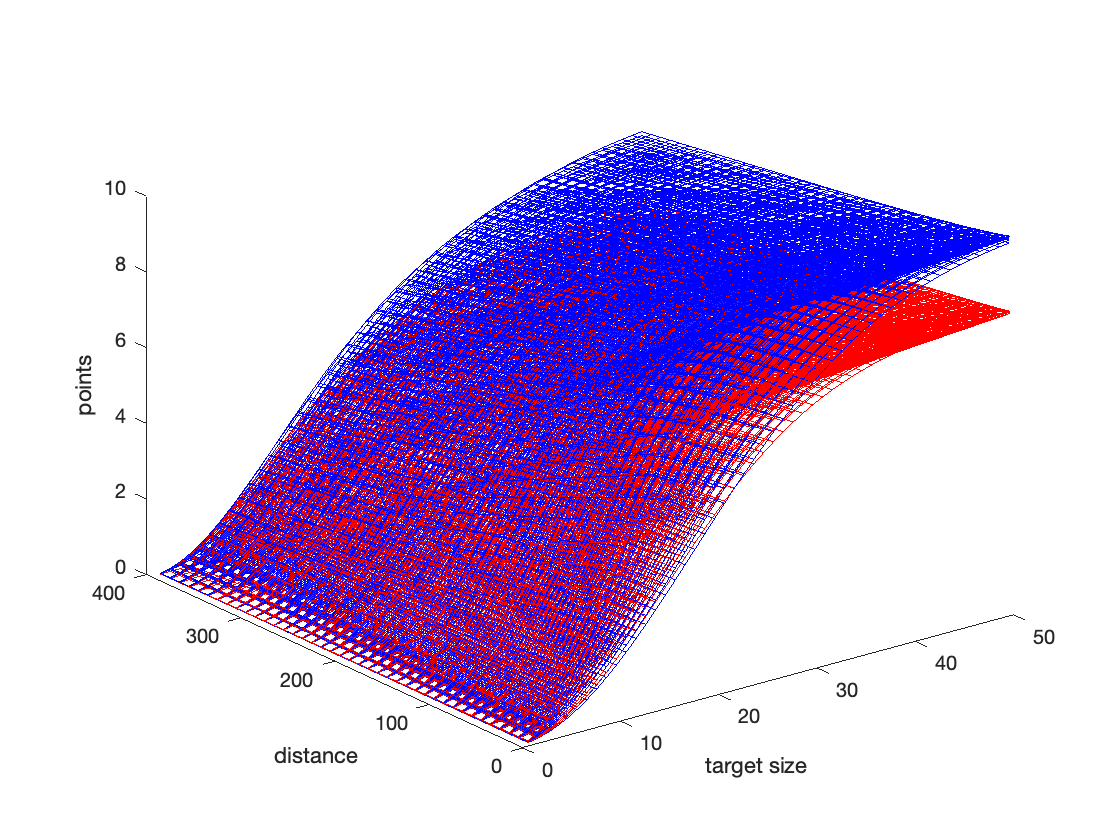

%Simulation of Aim 2 for grant

%Expected gain over various speeds, target sizes, and distances. SD
%(errors) are set for a given range with a direct relationship to speed.
%These values will likely change across participants. 

totTime = 5; % secs
speeds = 100:50:500; %mm/s
errors = 10:18; %motor sigma
distance = 5:10:400; %mm
penalty = 1; % secs
target = 1:50; %mm


for tt = 1:length(target) %loop over all target sizes
    target1 = target(tt);
    target2 = target1 * 1.2; %20% increase
   
    for dd = 1:length(distance) %loop over all distances
        
        for ss = 1:length(speeds) %loop over all speeds (incorporates errors)
            time = distance(dd)/speeds(ss);
            elapsed = totTime - time;
            probHit1 = raylcdf(target1,errors(ss));
            probHit2 = raylcdf(target2,errors(ss));
            
            %this simple point calculation only works because using 5-seconds. 
            %If another time is used a more complex points calculation is
            %needed. 
            points1(tt,dd,ss) = (elapsed*2) * probHit1;
            points2(tt,dd,ss) = (elapsed-penalty)*2 * probHit2;
        end
    end
end

%Can only plot one 3D slice at a time, this plot adds a new surface for
%each speed. 

%To plot only ONE speed, set ii equal to a single value. 
figure
for ii = 1:length(speeds)
hold on
surf(target,distance,points1(:,:,ii)','FaceAlpha',0,'EdgeColor','b')
surf(target,distance,points2(:,:,ii)','FaceAlpha',0,'EdgeColor','r')
hold off
xlabel('target size')
ylabel('distance')
zlabel('points')
view(3)
pause(.5)
end

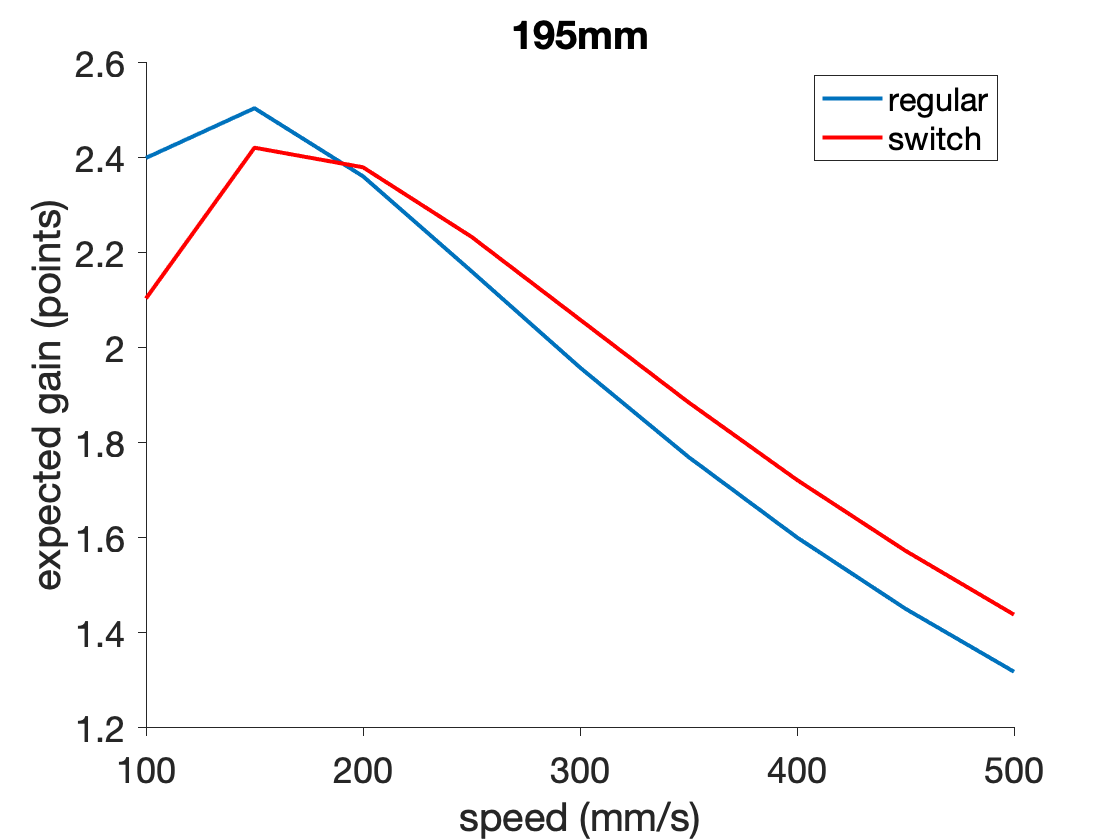

%2D plots showing only points across speed with target and distance fixed 
points2d1 = reshape(points1(10,20,:),[9,1]);
points2d2 = reshape(points2(10,20,:),[9,1]);

figure; hold on
plot(speeds,points2d1,'LineWidth',2)
plot(speeds,points2d2,'r','LineWidth',2)
xlabel('speed (mm/s)')
ylabel('expected gain (points)')
title([num2str(distance(20)), 'mm'])
legend('regular','switch','Location','best')
set(gca, 'TickDir', 'out', 'FontSize', 18)

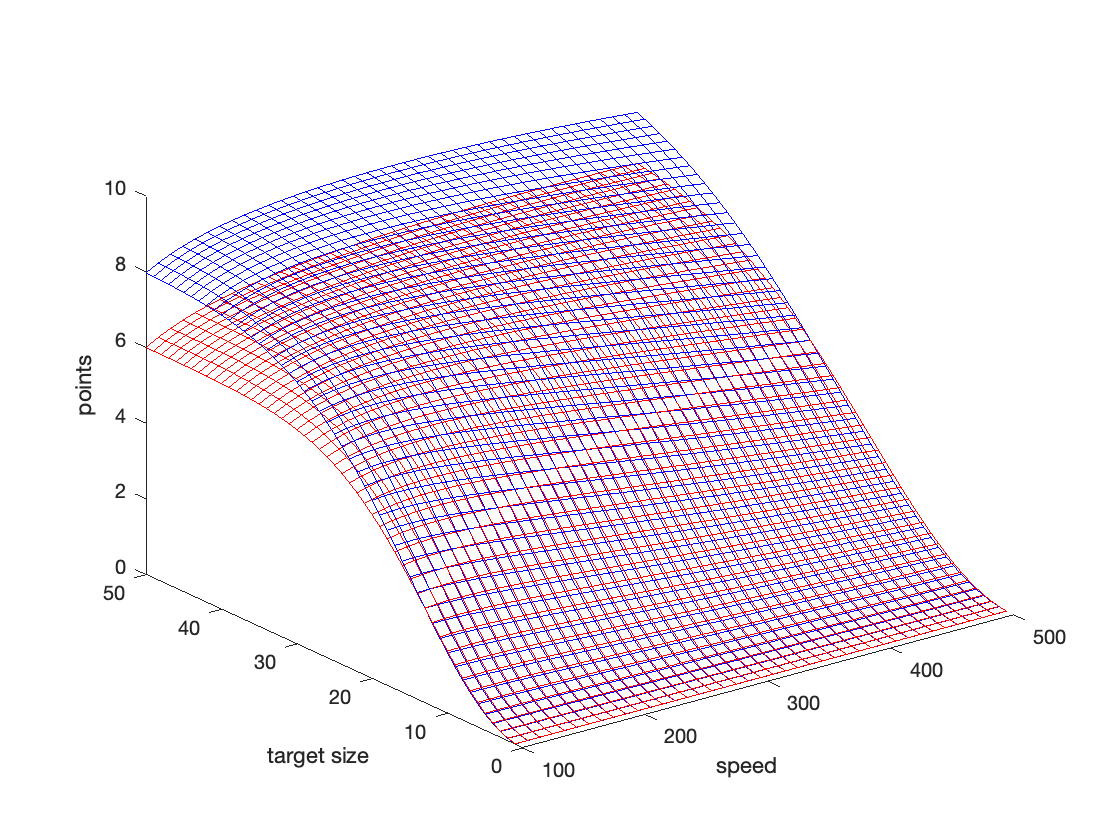

%Fixing distance and looking only at target size vs speed (easier plotting)

clear all
totTime = 5; % secs
speeds = 100:10:500; %mm/s
errors = 15:.2:23; %motor sigma
distance = 100; %mm
penalty = 1; % secs
target = 1:50; %mm

for tt = 1:length(target)
    target1 = target(tt);
    target2 = target1 * 1.2; %20% increase
   
    for dd = 1:length(distance)
        
        for ss = 1:length(speeds)
            time = distance(dd)/speeds(ss);
            elapsed = totTime - time;
            probHit1 = raylcdf(target1,errors(ss));
            probHit2 = raylcdf(target2,errors(ss));
            points1(ss,tt) = (elapsed*2) * probHit1;
            points2(ss,tt) = (elapsed-penalty)*2 * probHit2;
        end
    end
end
figure
hold on
surf(speeds,target,points1','FaceAlpha',0,'EdgeColor','b')
surf(speeds,target,points2','FaceAlpha',0,'EdgeColor','r')
xlabel('speed')
ylabel('target size')
zlabel('points')
view(3)